1. How many degrees of freedom (n) does this mechanism possess?

Applying Grubler’s formula, we yield:

4*3 - 5*2 = 2

2. Where would you attach motors to control the position of the end effector in the plane?

I would place the motors on the two encircled joints. For the case of the 

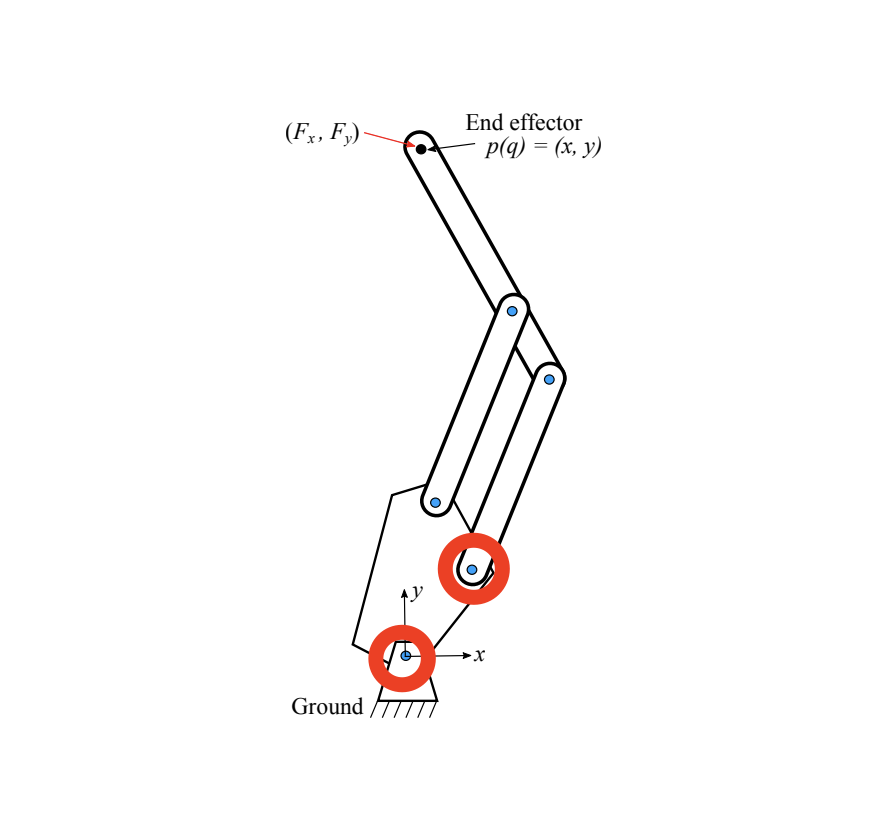

imshow(imread("qrd_xfer.png"))

3. Based on your choice, define joint position vectors q ∈ R n and derive forward kinematic equations that relate the inputs (motor angles) to the outputs (end effector position in Cartesian coordinate, i.e. p = (x, y)).

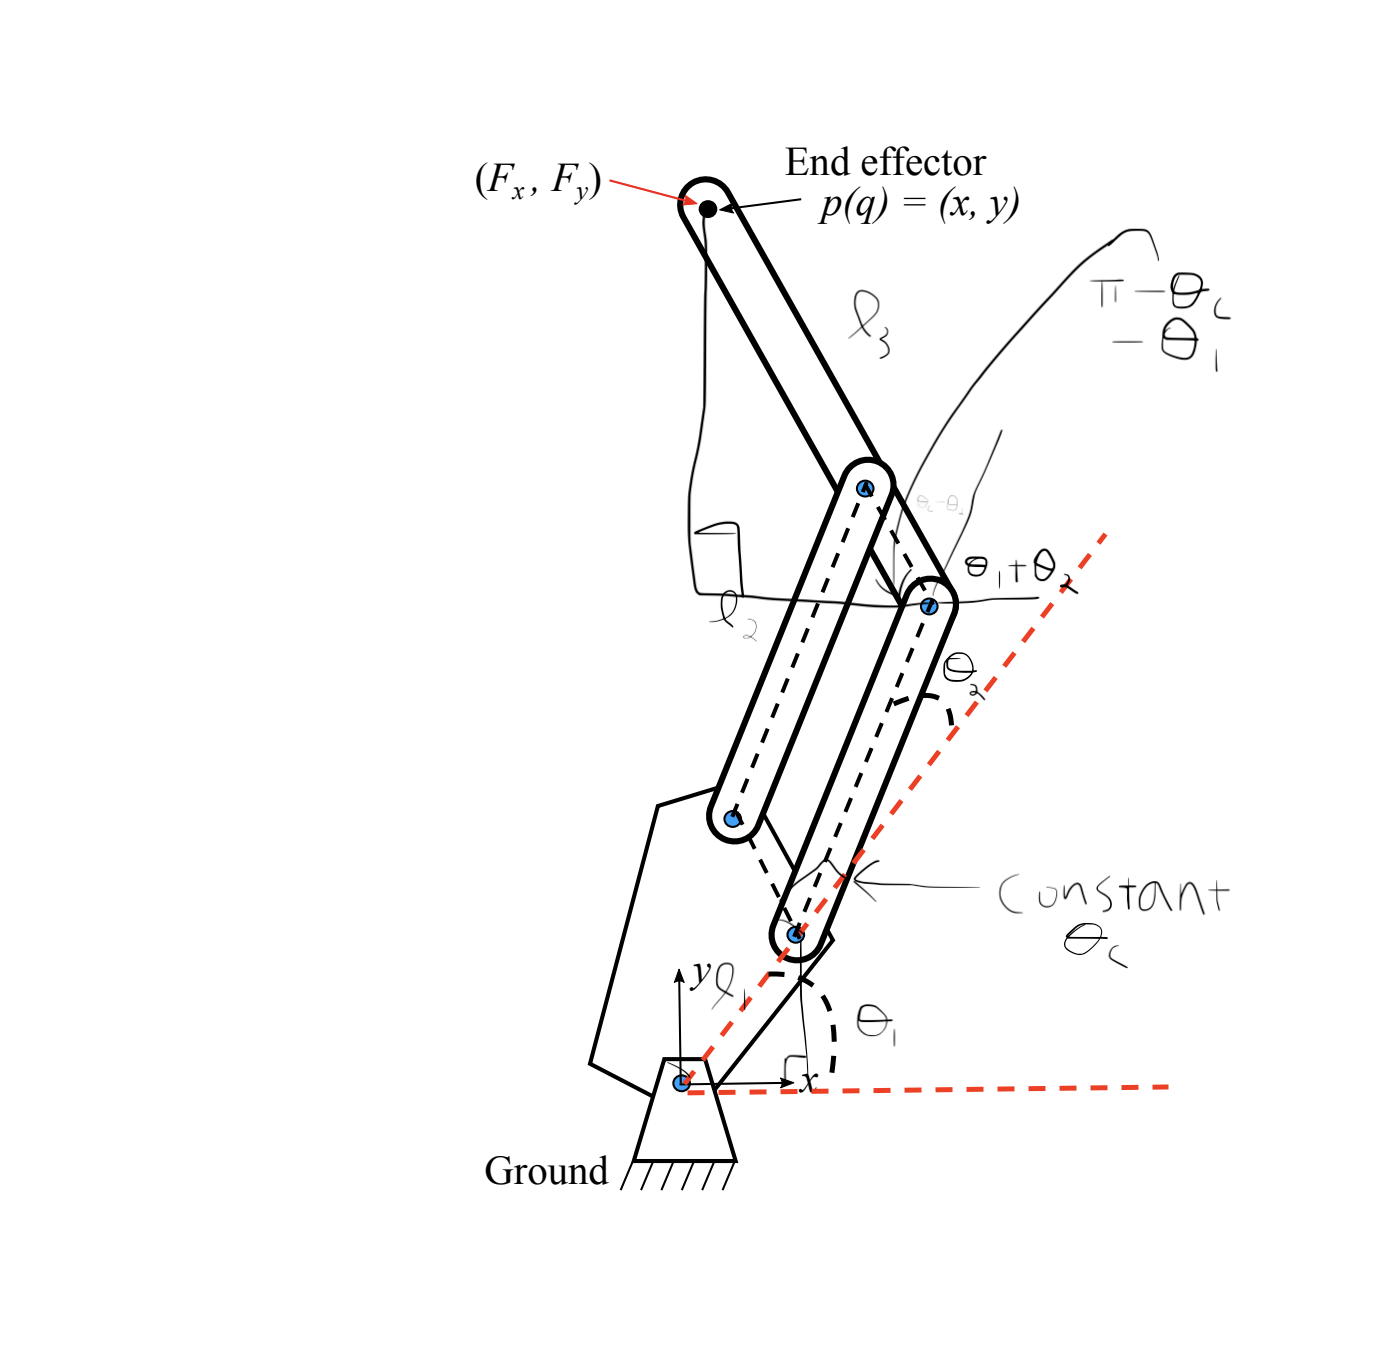

imshow(imread("p2.png"))

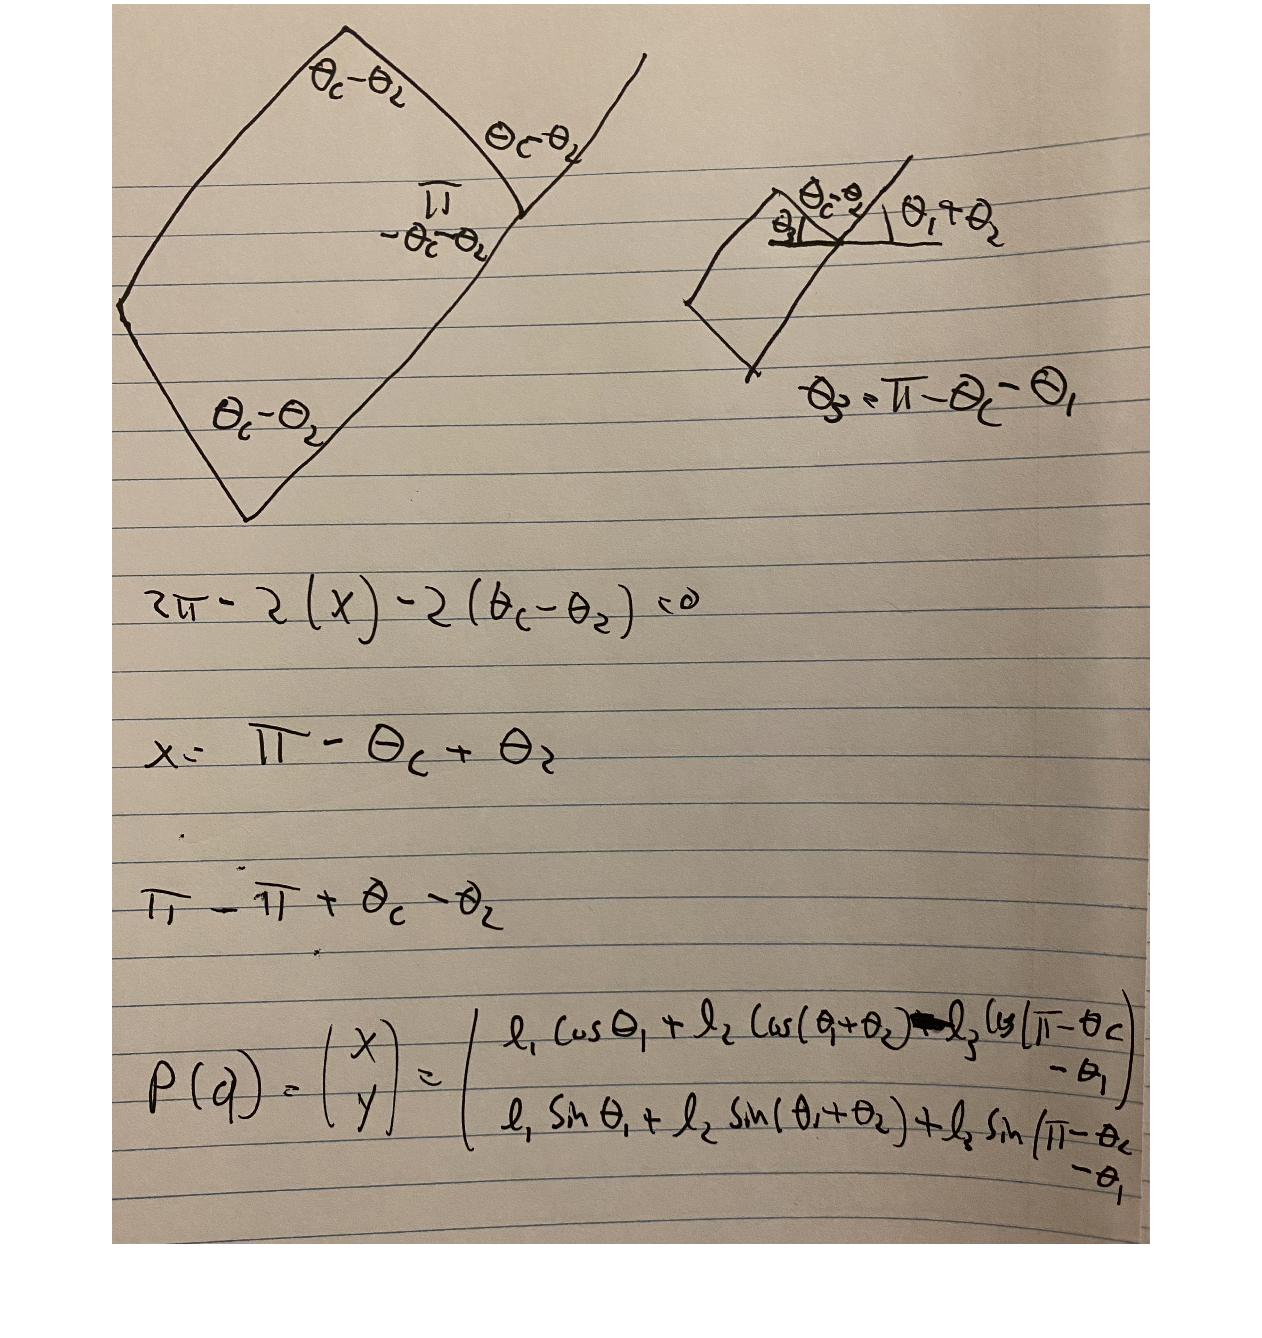

imshow(imread("p3.png"))

As defined in the pictures, we can write the kinematic equation to be the following:

%defining symbolic variables
syms l1 l2 l3 t1 t2 tc;

% defining x and y
x = l1 * cos(t1) + l2 * cos(t1+t2) - l3 * cos(pi-tc-t1);
y = l1 * sin(t1) + l2 * sin(t1+t2) + l3 * sin(pi-tc-t1);

%defining the kinematic equation as a matrix of x and y
p = [x y];

4. Obtain the Jacobian matrix J(q) = dp/dq symbolically in Matlab. 

%Calculating jacobian of the forward kinematic equation
J = jacobian(p, [t1 t2]);
disp(J)

$$\left(\begin{array}{cc} -l_{2}\,\sin\left(t_{1}+t_{2}\right)-l_{3}\,\sin\left(t_{1}+\mathrm{tc}\right)-l_{1}\,\sin\left(t_{1}\right) & -l_{2}\,\sin\left(t_{1}+t_{2}\right)\\ l_{2}\,\cos\left(t_{1}+t_{2}\right)+l_{3}\,\cos\left(t_{1}+\mathrm{tc}\right)+l_{1}\,\cos\left(t_{1}\right) & l_{2}\,\cos\left(t_{1}+t_{2}\right) \end{array}\right)$$

5. Use this Jacobian to relate output forces (Fx, Fy) at the tip of the arm to statically equivalent input torques (τ1, τ2).

From class (and 5.4 from the book) we learned that (Fx, Fy) = (J^T)^{-1} (τ1, τ2) so to relate the two we see we just need to calculate the inverse of the transpose of the Jacobian, which we can again do in matlab:

%Calculate the inverse of the transpose of the jacobian
JTinv = inv(transpose(J));
disp(JTinv)

$$\begin{array}{l} \left(\begin{array}{cc} -\frac{\cos\left(t_{1}+t_{2}\right)}{\sigma_{2}} & \frac{l_{2}\,\cos\left(t_{1}+t_{2}\right)+l_{3}\,\cos\left(t_{1}+\mathrm{tc}\right)+l_{1}\,\cos\left(t_{1}\right)}{\sigma_{1}}\\ -\frac{\sin\left(t_{1}+t_{2}\right)}{\sigma_{2}} & \frac{l_{2}\,\sin\left(t_{1}+t_{2}\right)+l_{3}\,\sin\left(t_{1}+\mathrm{tc}\right)+l_{1}\,\sin\left(t_{1}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,l_{3}\,\cos\left(t_{1}+t_{2}\right)\,\sin\left(t_{1}+\mathrm{tc}\right)-l_{2}\,l_{3}\,\cos\left(t_{1}+\mathrm{tc}\right)\,\sin\left(t_{1}+t_{2}\right)+l_{1}\,l_{2}\,\cos\left(t_{1}+t_{2}\right)\,\sin\left(t_{1}\right)-l_{1}\,l_{2}\,\sin\left(t_{1}+t_{2}\right)\,\cos\left(t_{1}\right)\\ \sigma_{2}=l_{3}\,\cos\left(t_{1}+t_{2}\right)\,\sin\left(t_{1}+\mathrm{tc}\right)-l_{3}\,\cos\left(t_{1}+\mathrm{tc}\right)\,\sin\left(t_{1}+t_{2}\right)+l_{1}\,\cos\left(t_{1}+t_{2}\right)\,\sin\left(t_{1}\right)-l_{1}\,\sin\left(t_{1}+t_{2}\right)\,\cos\left(t_{1}\right) \end{array}$$